# **整体优化**

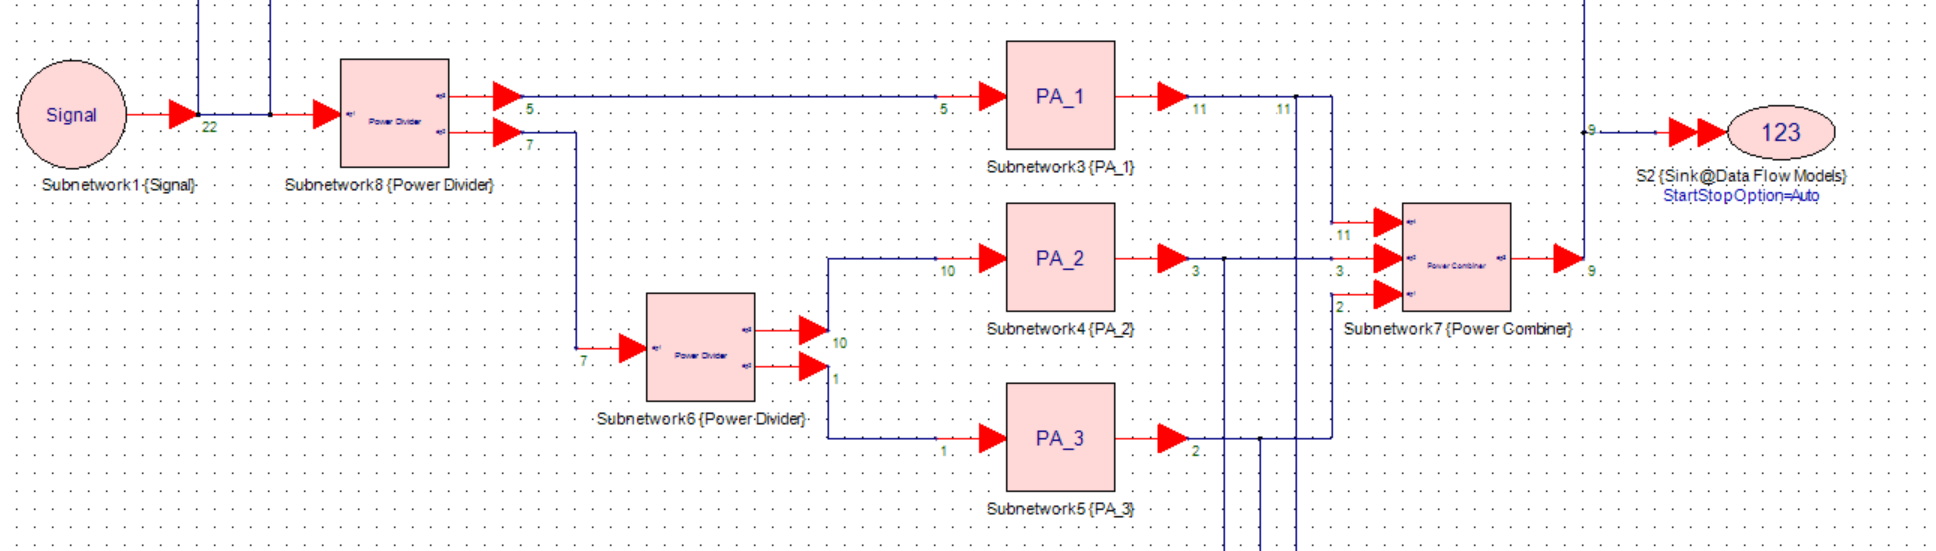

% 运行前请先将子文件夹添加到路径
clc;

## -----------------------------Model A Train----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Train();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2);
Sys_output = Data_matrix(:,end-1) + 1i * Data_matrix(:,end);
PA1_output = Data_matrix(:,3) + 1i * Data_matrix(:,4);
PA2_output = Data_matrix(:,5) + 1i * Data_matrix(:,6);
PA3_output = Data_matrix(:,7) + 1i * Data_matrix(:,8);
PA1_input = 0.5*Sys_input;
PA2_input = 0.25*Sys_input;
PA3_input = 0.25*Sys_input;
% 参数需要保持一致
path = 'Method_A\Whole\C_opt.mat';
M = 0;
N = 1:1:20;
nmse = zeros(length(M),length(N));

## 【训练】整体训练

for i= 1:length(M)
    fprintf('-------- M= %f --------\n', M(i));
    for j =1:length(N)
        % 模型训练
        DPD_coefficient = Train_Voltrra(M(i),N(j),dim,Sys_input,Sys_output);
        save(path, 'DPD_coefficient');
        % 模型精度
        nmse(i,j) = NMSE_dB(Sys_input, DPD_Voltrra(Sys_output,M(i),N(j),path));
    end
end

-------- M= 0.000000 --------



save('nmse.mat', 'nmse');

[min_value, index] = min(nmse(:))

min_value = -30.4195

index = 12

[M_opt, N_opt] = ind2sub(size(nmse), index)

M_opt = 1

N_opt = 12

% figure();
% imagesc(nmse);                    % 用 imagesc 显示矩阵
% colormap(jet);                 % 使用 jet 配色方案
% colorbar;                      % 添加颜色条